# Riepilogo 01: calcoli da pdf, cdf, icdf di una v.a.

Nota: i grafici inseriti nelle soluzioni non sono mai richiesti all'esame, e quindi nemmeno nelle tracce degli esercizi. 

All'esame i grafici sono spesso inseriti nella traccia, per maggiore chiarezza sul significato del quesito.

## 1 - Calcoli nota la pdf di una v.a.

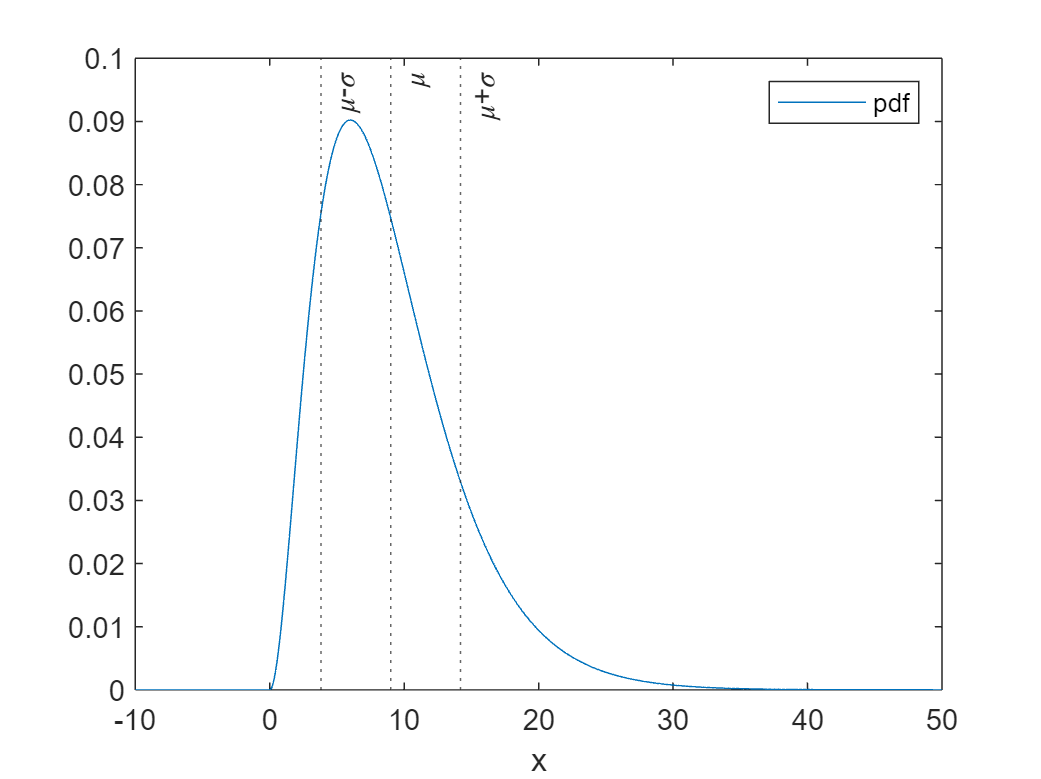

% Dati
% f = @(x) % pdf della v.a. X (funzione di x)
% x % vettore riga di valori equispaziati in cui calcolare la pdf, e da considerare nei calcoli

% Domande
% fX = vettore riga dei valori della pdf calcolata in x
% FX = vettore riga dei valori della cdf calcolata in x
%
% m0 = momento di ordine 0 della v.a.
% m0_teo = valore teorico che deve assumere m0
%
% m1 = momento di ordine 1 della v.a.
% m2 = momento di ordine 2 della v.a.
%
% mc1 = momento centrale di ordine 1 della v.a.
% mc1_teo = valore teorico che deve assumere mc1
%
% mc2 = momento centrale di ordine 2 della v.a.
% 
% mu = media della v.a.
% P = potenza della v.a.
% sigma2 = varianza della v.a.
% sigma = deviazione standard della v.a.
%
% MAD = mean absolute deviation della v.a.
% moda = moda o valore modale della v.a.

% Nota
% Tutti gli integrali sono da calcolarsi come sommatorie

% Codice iniziale
clear
n = 3; mu1 = 3; % parametri della pdf

f = @(x) gampdf(x,n,mu1); % pdf

Nx = 1e3+1; % numero di valori di x da considerare
xmin = -10; xmax = 50; % estremi dei valori di x da considerare
x = linspace(xmin,xmax,Nx); % Nx valori equispaziati tra xmin e xmax

### Soluzione

fX = f(x)

fX =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


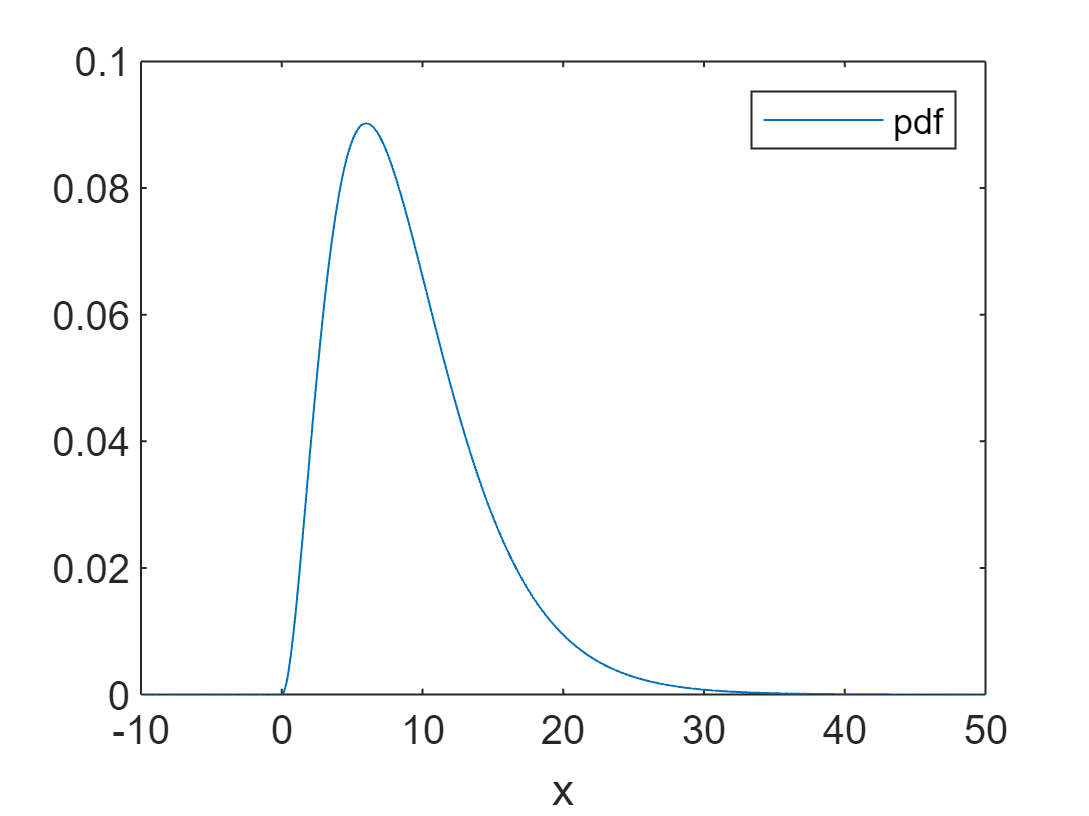

plot(x,fX) % i grafici non sono richiesti all'esame
xlabel('x')
legend('pdf')

Serve a calcolare gli integrali

dx = x(2)-x(1) % perché i valori di x sono equispaziati

dx = 0.0600


$$F\left(x\right)=\int_{-\infty }^x f\left(x^{\prime } \right){dx}^{\prime }$$


FX = cumsum(fX)*dx % la cdf è l'integrale da -Inf a x della pdf (= somma cumulativa)

FX =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


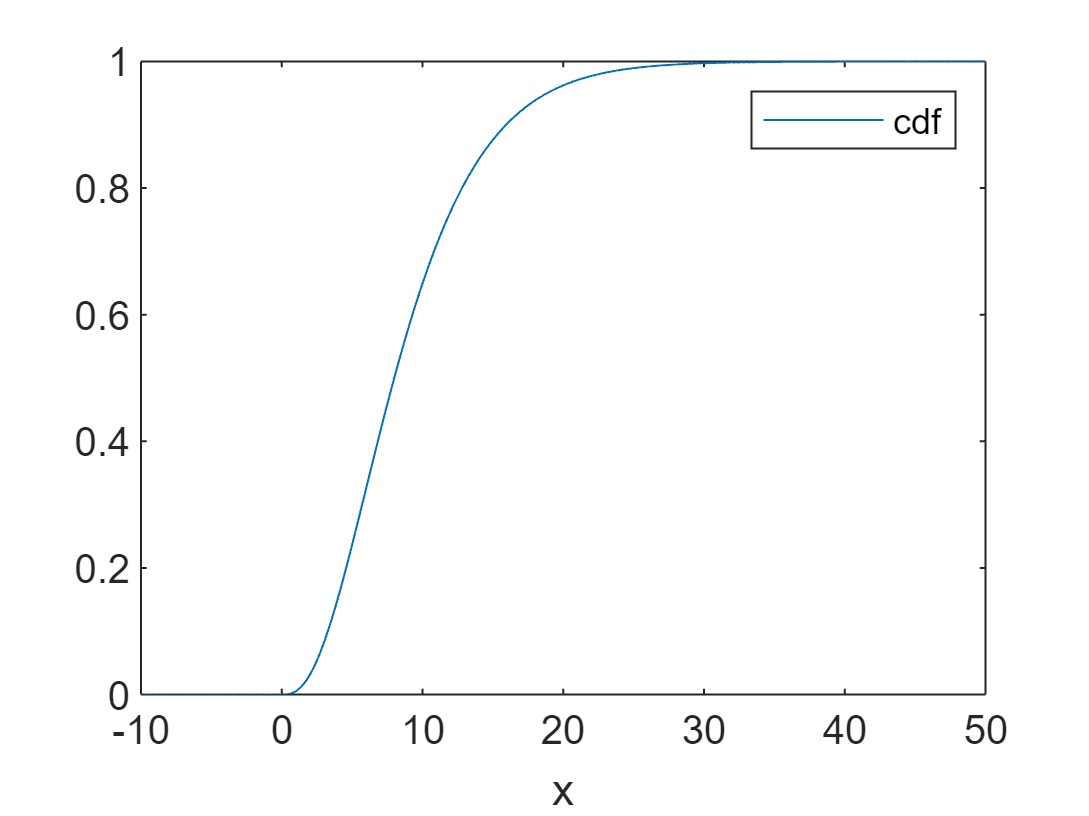

plot(x,FX) % i grafici non sono richiesti all'esame
xlabel('x')
legend('cdf')


$$m_0 =\int_{-\infty }^{+\infty } f\left(x\right)dx=1$$


m0 = sum(fX)*dx

m0 = 1.0000

m0_teo = 1 % il momento di ordine 0 ha valore 1 (condizione di normalizzazione)

m0_teo = 1


$$m_1 =\int_{-\infty }^{+\infty } x\;f\left(x\right)dx=\mu$$


m1 = sum(fX.*x)*dx % momento di ordine 1

m1 = 8.9995

mu = m1 % la media è il momento di ordine 1

mu = 8.9995


$$m_2 =\int_{-\infty }^{+\infty } x^2 \;f\left(x\right)dx=P$$


m2 = sum(fX.*x.^2)*dx % momento di ordine 2

m2 = 107.9743

P = m2 % la potenza è il momento di ordine 2

P = 107.9743


$${mc}_1 =\int_{-\infty }^{+\infty } \left(x-\mu \;\right)\;f\left(x\right)dx=0$$


mc1 = sum(fX.*(x-mu))*dx

mc1 = 8.1126e-05

mc1_teo = 0 % il momento centrale di ordine 1 ha valore 0 

mc1_teo = 0


% è una proprietà della media, in quanto baricentro della pdf
% una formula alternativa per calcolare mc1 sarebbe:
% mc1 = m1 - m1


$${mc}_2 =\int_{-\infty }^{+\infty } {\left(x-\mu \;\right)}^2 \;f\left(x\right)dx=\sigma^2$$


mc2 = sum(fX.*(x-mu).^2)*dx

mc2 = 26.9822

mc2 = P - mu^2 % formula alternativa

mc2 = 26.9830

sigma2 = mc2 % la varianza è il momento centrale di ordine 2

sigma2 = 26.9830

sigma = sqrt(sigma2)

sigma = 5.1945


$$MAD=\int_{-\infty }^{+\infty } |x-\mu \;|\;f\left(x\right)dx$$


MAD = sum(abs(x-mu).*fX*dx) % mean absolute deviation

MAD = 4.0323

% E' il valore atteso del modulo di x-mu


$$moda=x\;\;\;\;\mathrm{tale}\;\mathrm{che}\;\;\;\;f\left(x\right)=\max$$


[maxfX,i] = max(fX) % i = indice in cui fX assume il valore massimo

maxfX = 0.0902

i = 268

moda = x(i) % valore di x in cui fX assume il valore massimo

moda = 6.0200

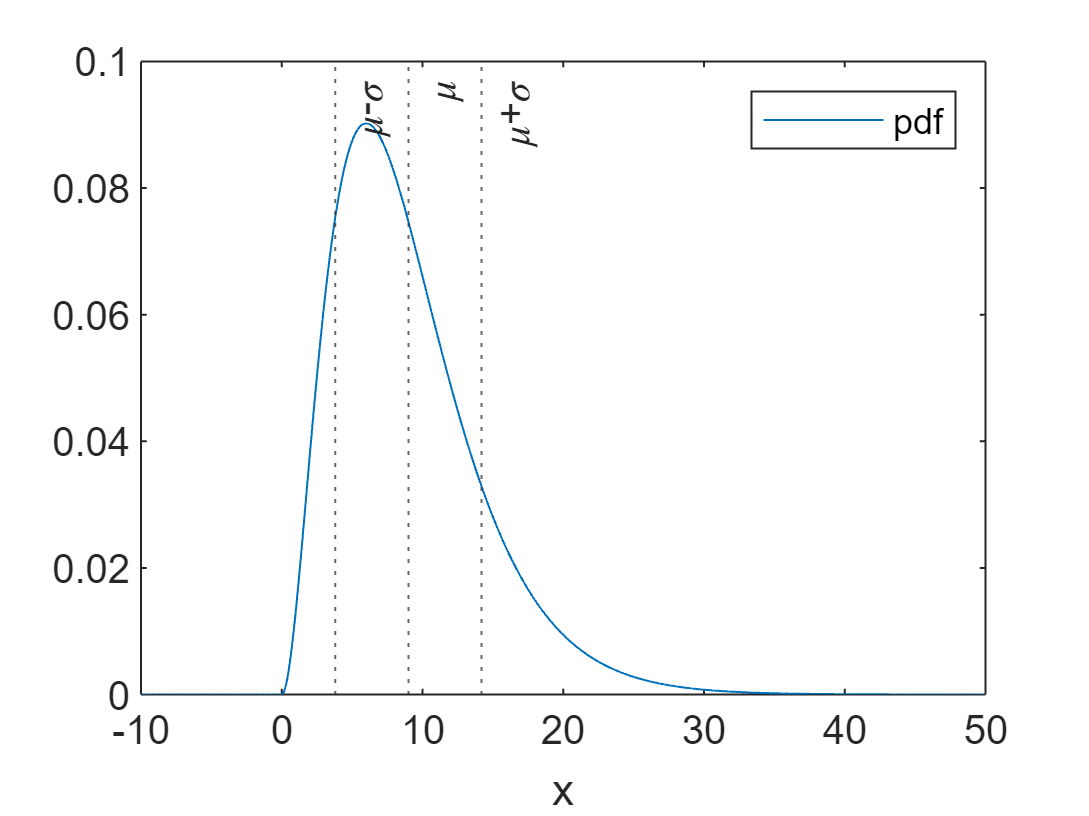

% Grafico nella traccia
plot(x,fX) % i grafici non sono richiesti all'esame
xline(mu,':','\mu')
xline(mu+sigma,':','\mu+\sigma')
xline(mu-sigma,':','\mu-\sigma')
xlabel('x')
legend('pdf')

## 2 - Calcoli nota la cdf di una v.a.

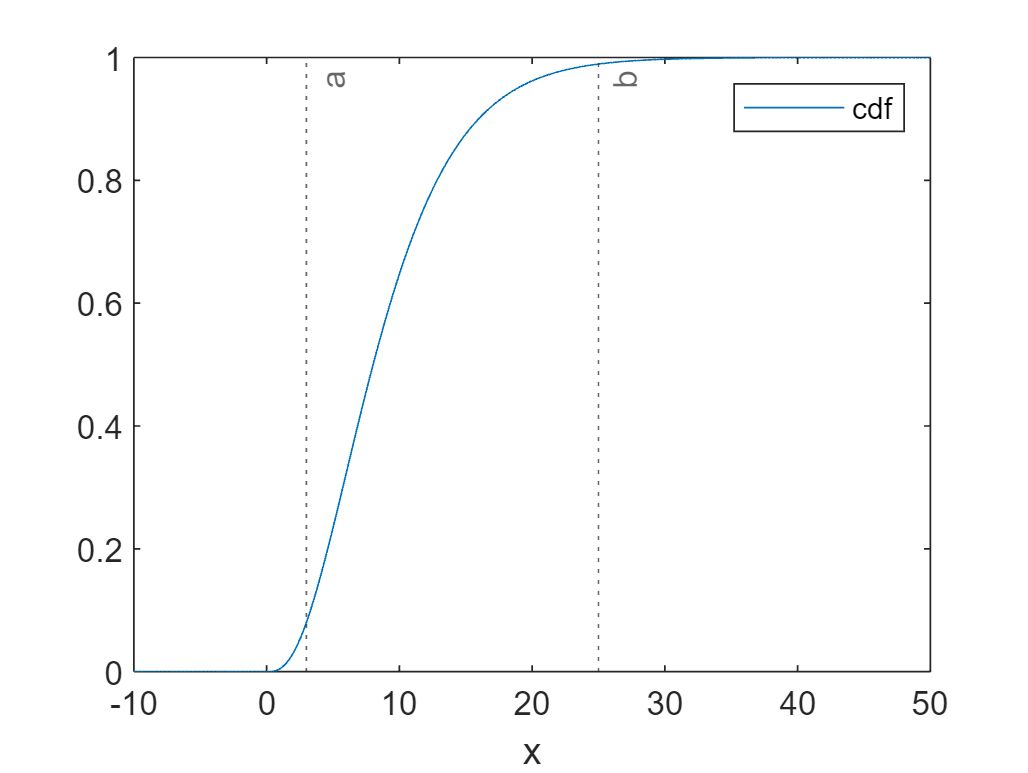

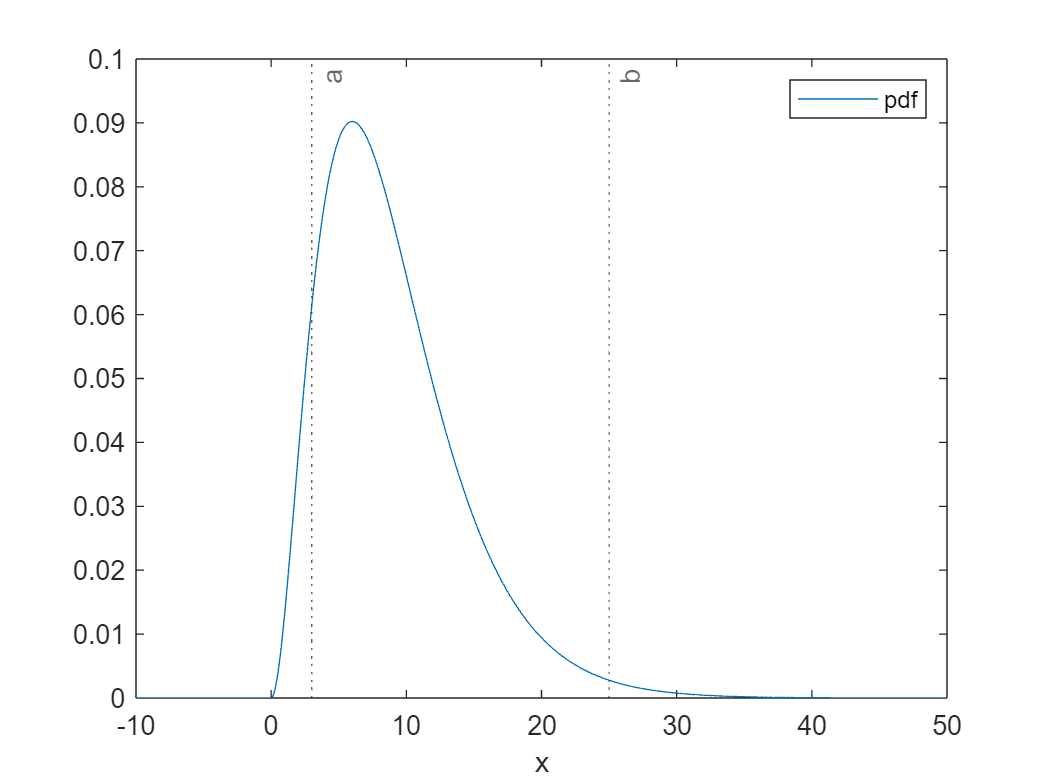

% Dati
% F = @(x) % cdf della v.a. X (funzione di x)
% a = scalare, valore assegnato di x
% b = scalare, valore assegnato di x, maggiore di a

% Domande
% Pa = Prob(X = a)
% Pb = Prob(X = b)
% Pab = Prob(X in [a,b]) (probabilità che X assuma un valore compreso tra a e b)
% Pab_not = Prob(X not in [a,b]) (probabilità che X NON assuma un valore compreso tra a e b)
% Pa_minore = Prob(X <= a) probabilità che X assuma valore <= a
% Pa_maggiore = Prob(X >= a) probabilità che X assuma valore >= a

% Codice iniziale
clear
n = 3; mu1 = 3; % parametri della pdf

F = @(x) gamcdf(x,n,mu1); % pdf
a = 3; b = 25; % valori


% Grafico nella traccia
Nx = 1e3+1; % numero di valori di x da considerare
xmin = -10; xmax = 50; % estremi dei valori di x da considerare
x = linspace(xmin,xmax,Nx); % Nx valori equispaziati tra xmin e xmax

f = @(x) gampdf(x,n,mu1) % pdf

f = function_handle with value:
    @(x)gampdf(x,n,mu1)

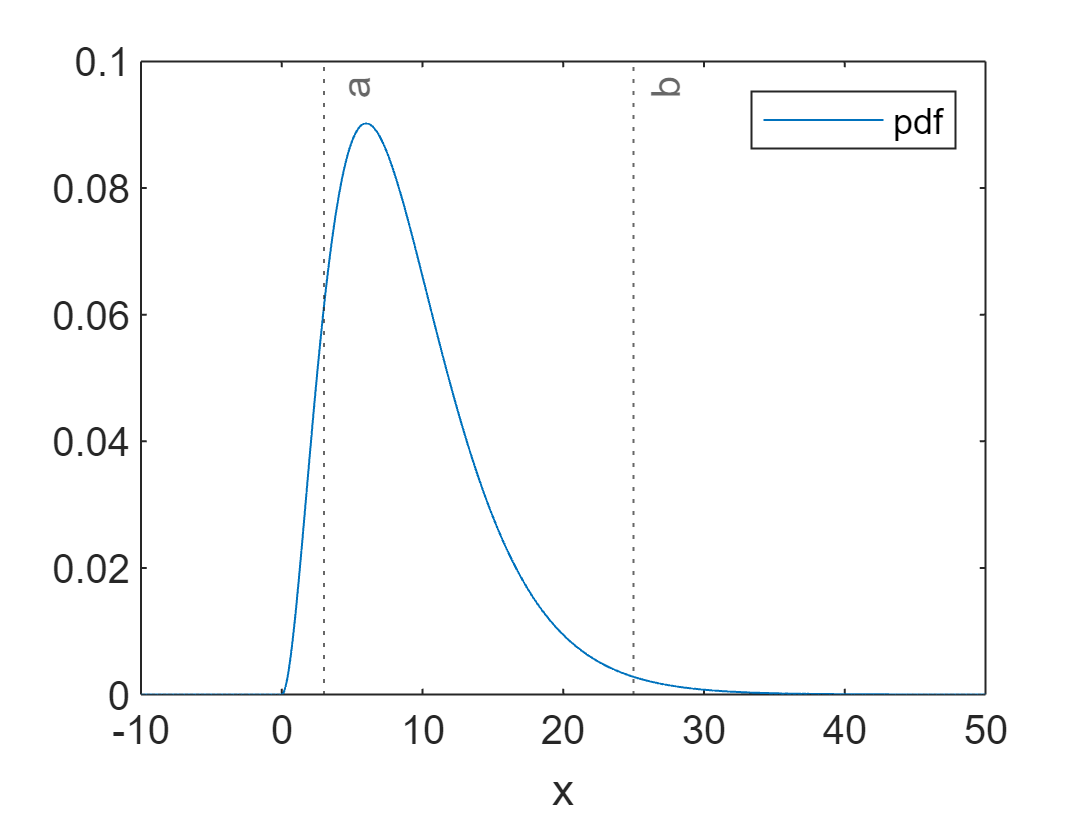

plot(x,f(x))
xline(a,':','a')
xline(b,':','b')
xlabel('x')
legend('pdf')

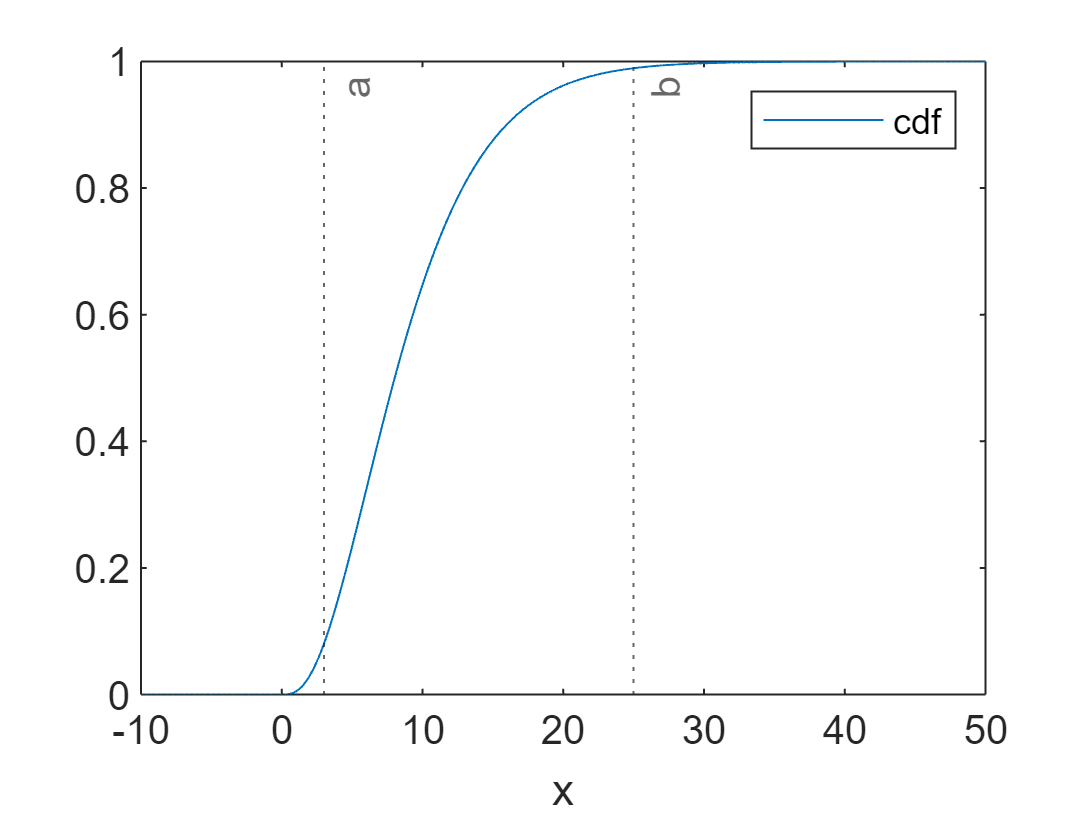


plot(x,F(x))
xline(a,':','a')
xline(b,':','b')
xlabel('x')
legend('cdf')

### Soluzione

Pa = 0 % la prob. che una v.a. continua assuma un singolo valore reale è 0

Pa = 0

Pb = 0 % la prob. che una v.a. continua assuma un singolo valore reale è 0

Pb = 0

Pab = F(b)-F(a) % probabilità che X assuma un valore compreso tra a e b

Pab = 0.9091

Pab_not = 1 - Pab % probabilità che X NON assuma un valore compreso tra a e b

Pab_not = 0.0909

Pa_minore = F(a) % è il significato della cdf: Prob(X <= a)

Pa_minore = 0.0803

Pa_maggiore = 1-F(a) % probabilità che X assuma valore >= a

Pa_maggiore = 0.9197

## 3 - Calcoli nota la icdf di una v.a.

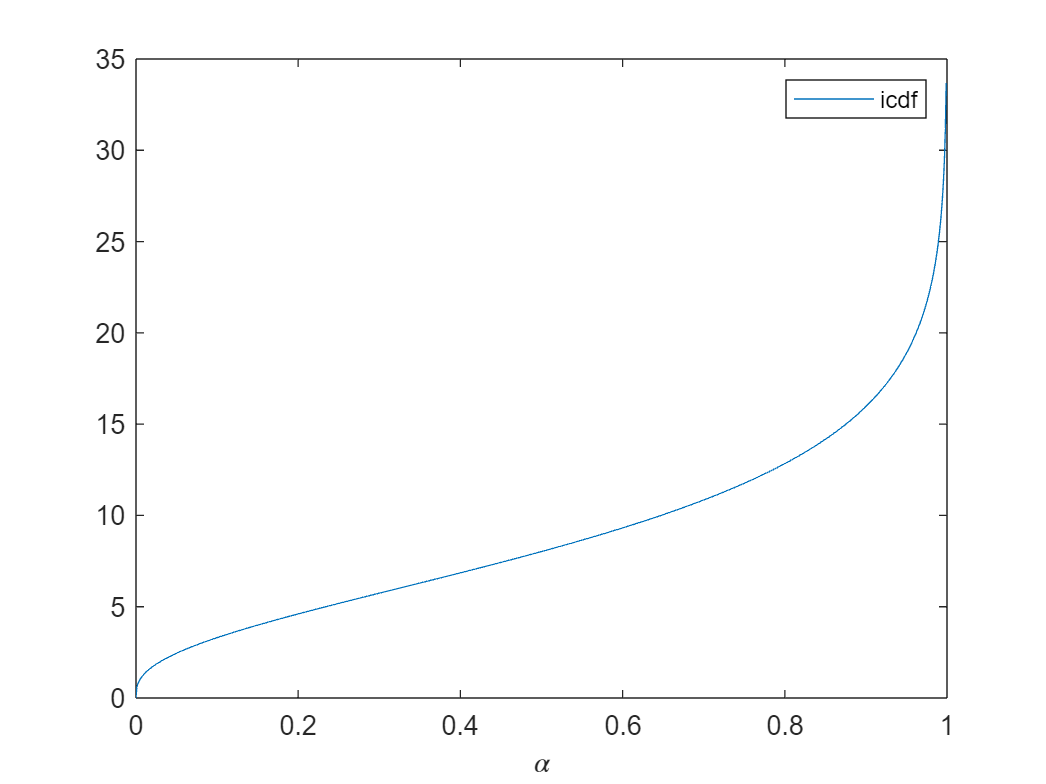

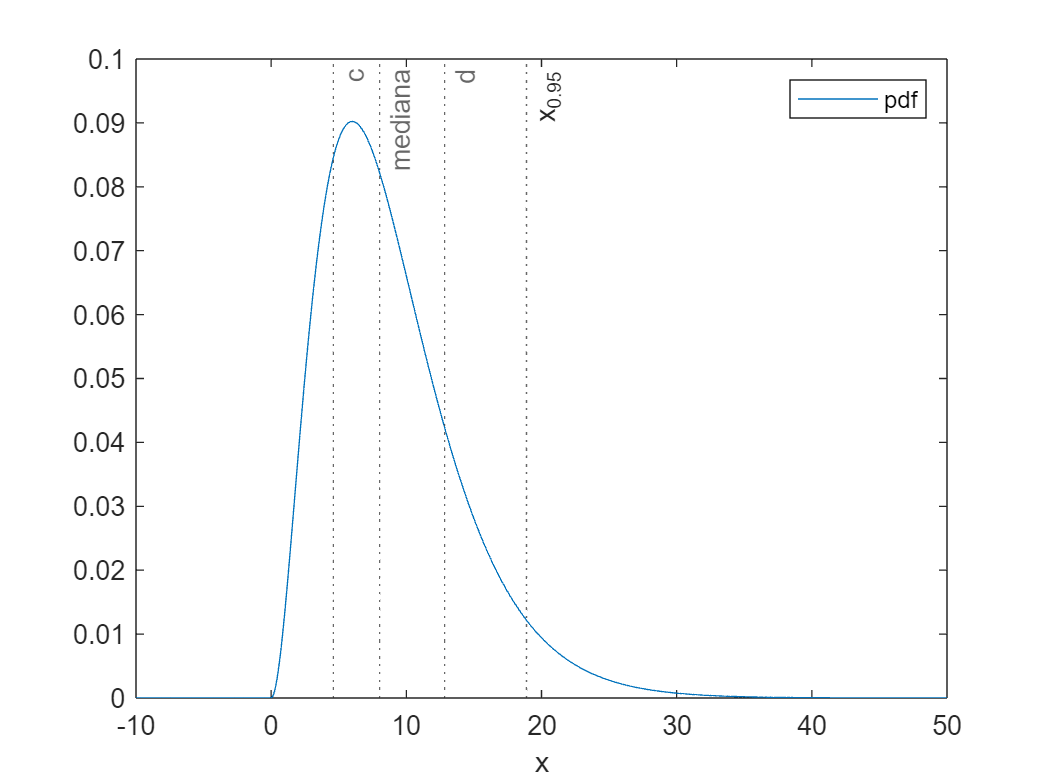

% Dati
% invF = @(alpha) % icdf della v.a. (funzione di alpha)
% p_left = probabilità a sinistra dell'intervallo da calcolare
% p = probabilità dell'intervallo da calcolare

% Domande
% a = estremo sinistro dell'intervallo di prob. p con probabilità a sinistra p_left
% b = estremo destro dell'intervallo di prob. p con probabilità a sinistra p_left
%
% c = estremo sinistro dell'intervallo di prob. p *a code di area uguale*
% d = estremo destro dell'intervallo di prob. p *a code di area uguale*
%
% q1 = primo quartile della v.a.
% q2 = secondo quartile della v.a.
% q3 = terzo quartile della v.a.
% mediana = mediana della v.a.
%
% IQR = range interquartile della v.a.
% x95 = quantile 0.95 della v.a. = 95° percentile della v.a.

% Codice iniziale
clear
n = 3; mu1 = 3; % parametri della pdf

invF = @(alpha) gaminv(alpha,n,mu1); % icdf

p_left = 0.1;
p = 0.6;

### Soluzione


$$a=F^{-1} \left(p_{\mathrm{left}} \right)$$



$$b=F^{-1} \left(p_{\mathrm{left}} +p\right)$$


a = invF(p_left)

a = 3.3062

b = invF(p_left+p)

b = 10.8467


$$c=F^{-1} \left(\frac{1-p}{2}\right)$$



$$d=F^{-1} \left(\frac{1+p}{2}\right)$$


c = invF((1-p)/2)

c = 4.6051

d = invF((1+p)/2)

d = 12.8371

$q_1 =F^{-1} \left(0\ldotp 25\right)$ ecc.

q1 = invF(0.25)

q1 = 5.1819

q2 = invF(0.5)

q2 = 8.0222

q3 = invF(0.75)

q3 = 11.7612

mediana = q2 % il secondo quartile è la mediana

mediana = 8.0222


$$IQR=q_3 -q_1$$


IQR = q3 - q1

IQR = 6.5793

$x_{\alpha \;} =F^{-1} \left(\alpha \;\right)$ con $\alpha =0\ldotp 95$

x95 = invF(0.95)

x95 = 18.8874

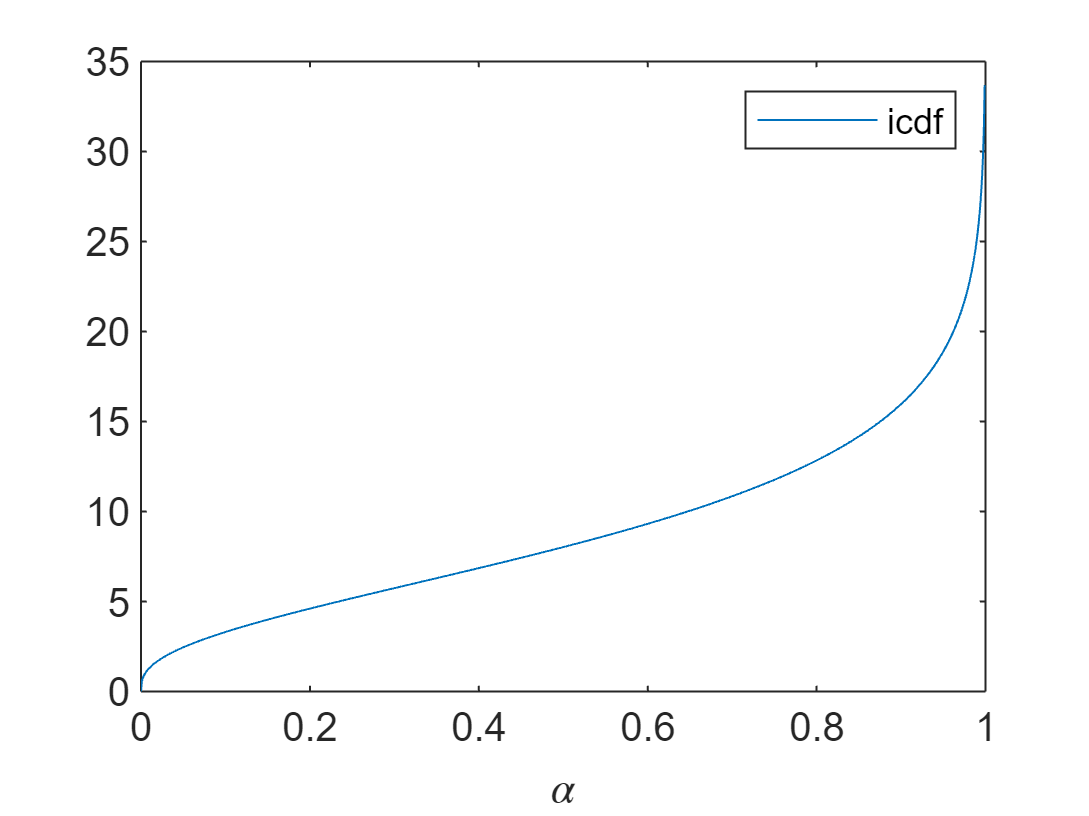

% Grafico nella traccia
Nx = 1e3+1;
alpha = linspace(0,1,Nx);
plot(alpha,invF(alpha))
xlabel('\alpha')
legend('icdf')

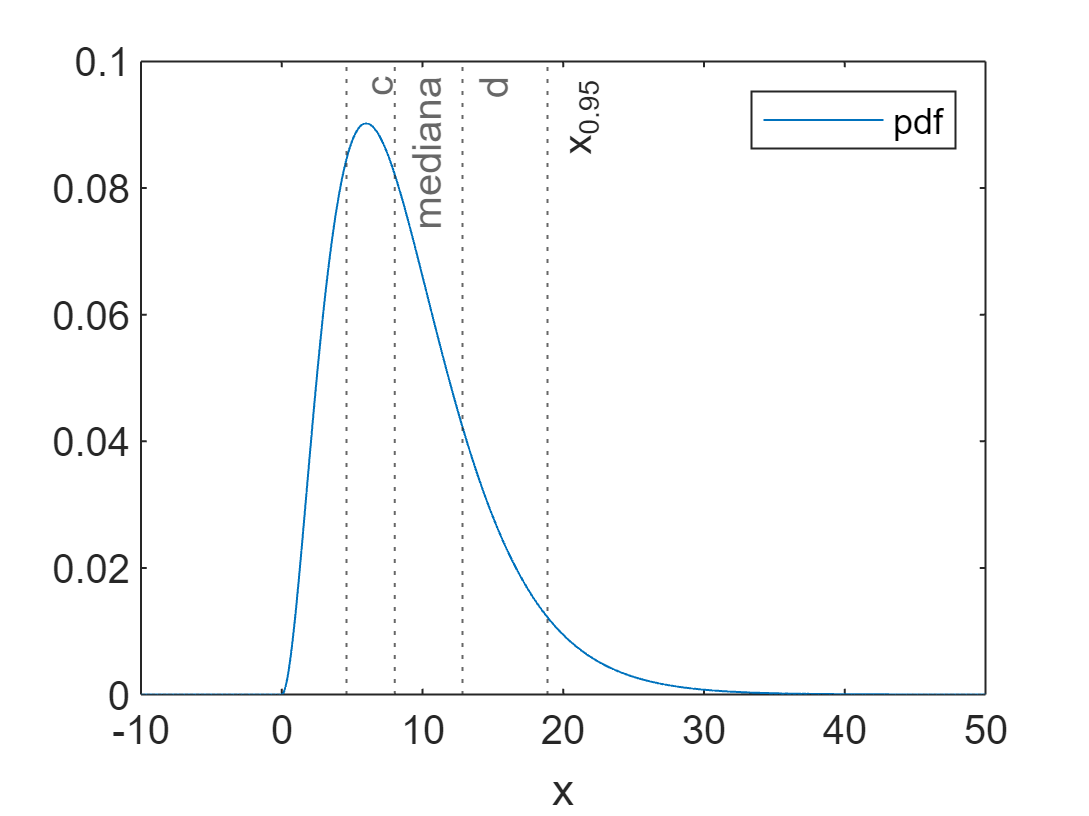


f = @(x) gampdf(x,n,mu1); % pdf
xmin = -10; xmax = 50; % estremi dei valori di x da considerare
x = linspace(xmin,xmax,Nx);
plot(x,f(x))
xline(c,':','c')
xline(d,':','d')
xline(mediana,':','mediana')
xline(x95,':','x_{0.95}')
xlabel('x')
legend('pdf')